# Implementation of ArcFace in MATLAB

ArcFaceにてペットの顔画像を学習し、未知のペット画像に対してそれぞれの犬種（猫種？）との類似度を計算するデモスクリプトです。

 This is a demo script that train ArcFace about the face images of pets and calculates the similarity between each breed of dog (or cat?) and an unknown pet image. 

## ・Reference

　- paper [[1801.07698] ArcFace: Additive Angular Margin Loss for Deep Face Recognition (arxiv.org)](https://arxiv.org/abs/1801.07698)

    - pytorch implementation [https://www.bing.com/search?q=arcface+github&qs=n&form=QBRE&sp=-1&pq=arcface+github&sc=2-14&sk=&cvid=4B4F5C3287C14111BA16CA650B50B6B4](https://www.bing.com/search?q=arcface+github&qs=n&form=QBRE&sp=-1&pq=arcface+github&sc=2-14&sk=&cvid=4B4F5C3287C14111BA16CA650B50B6B4)

　 - custom training loop example in MATLAB:

　　 "openExample('nnet/TrainNetworkUsingCustomTrainingLoopExample')" in command window

・Datasets: The Oxford-IIIT Pet Dataset(https://www.robots.ox.ac.uk/~vgg/data/pets/)

・trained model: Pet画像学習済みのデータはdlnet.matにあります trained model is saved as dlnet.end 

## Product used in development

#### ・MATLAB R2021b

#### ・Image Processing Toolbox

#### ・Deep Learning Toolbox

　　add on: `Deep Learning Toolbox Model for ResNet-50 Network`

#### ・Parallel Computing Toolbox `(if you want to use GPU in training)`

## To Run

Train and Test: 

Run all the program.Datasets is automatically downloaded from [Oxford-IIIT Pet Datse](https://www.robots.ox.ac.uk/~vgg/data/pets/)t ,

Test:

 Calculate similarity of breed of dog and cat and test images

- save test images to ./data/test (test images should be only face)

- input iamge filename in "test images" section

- Run section from "test images"

## Download Pet Datasets

download_datasets();

## Load Training Data

Pet画像をロード

%dataFoler = "./data/all";
dataFolder = "./data/face";
imds = imageDatastore(dataFolder, ...
    'IncludeSubfolders',true, ....
    'LabelSource','foldernames');

検証用データセット用に10%のデータを分割（splitEachLabel 関数を使用）

Partition the data into training and validation sets. Set aside 10% of the data for validation using the `splitEachLabel` function.

[imdsTrain,imdsValidation] = splitEachLabel(imds,0.9,'randomize');

ネットワークの入力画像サイズとデータ拡張を定義

Define Nework image input size and augmentation

inputSize = [100 100 3];
pixelRange = [-15 15];
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection', true, ...
    'RandRotation', [-30, 30], ...
    'RandYTranslation', pixelRange, ...
    'RandYTranslation',pixelRange, ...
    'RandScale', [0.6, 1.0]);

augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain,'DataAugmentation',imageAugmenter,'ColorPreprocessing','gray2rgb');

色変換のデータ拡張　色特徴ではなく、形状特徴によって判定してほしいため追加(茶色だから柴犬、ではなく耳とか目の形状で判定してほしいため　グレイスケールにするだけのほうがよい？)

無いほうが検証精度は高い（＝色特徴も使用したほうが検証精度は高い）

Color transform data augmentation. train network not to utilize color feature but texture shape feature(trained model should be distinguish shiba-dog because of not brown color but eye or ear shape. only gray scale transformation is more appropriate?)

Without this augmentaion, classification accuracy become higher ( = color feature enhance accuracy)

transimdsTrain = transform(augimdsTrain,@ColorAugmentation,'IncludeInfo',true);
augimdsTrain = transimdsTrain;

データの拡張を行わずに検証画像のサイズを自動的に変更するには、追加の前処理操作を指定せずに拡張画像データストアを使用

To automatically resize the validation images without performing further data augmentation, use an augmented image datastore without specifying any additional preprocessing operations.

augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsValidation,'ColorPreprocessing','gray2rgb');

学習データのクラス数を決定

Determine the number of classes in the training data.

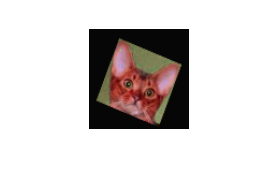

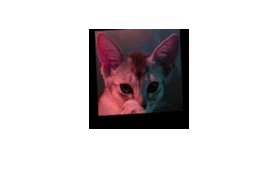

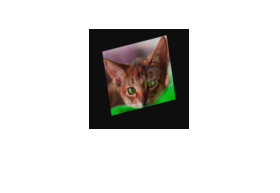

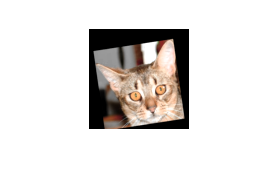

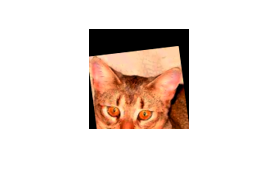

classes = categories(imdsTrain.Labels);
numClasses = numel(classes);

imgs_forShow = preview(augimdsTrain);
for i = (1:5)
    figure
    imshow(imgs_forShow{i})
end

## Define Network

Define the network for image classification.

%ArcFace loss function hyper parameter
scale = 30.0;
margin = 0.5;

%pretrained network is loaded
resnet = resnet50;
lgraph = resnet.layerGraph;

lgraph = lgraph.replaceLayer("input_1", imageInputLayer(inputSize,...
    "Name", "input", "Normalization", "rescale-zero-one", "Max", 255, "Min", 0));

% 出力層をArcFace用に特徴量層に置き換える
% Replace the output layer with a feature layer for ArcFace
lgraph = lgraph.removeLayers({'ClassificationLayer_fc1000', 'fc1000_softmax', 'fc1000'});
layers_out = [
    fullyConnectedLayer(512, "Name", "fc_output", "WeightsInitializer", "he")
    batchNormalizationLayer("Name", "bn_add");
    ArcFaceLayer(numClasses, scale, margin)
    softmaxLayer('Name','softmax')];% classificationLayer('Name', 'classification')];

lgraph_merge = addLayers(lgraph, layers_out);
lgraph_merge = connectLayers(lgraph_merge, "avg_pool", "fc_output");

% ArcFaceでは学習時に正解ラベルが必要であるため、ラベル用の入力層を追加
% ArcFace requires ground truth labels during training, so add an input
% layer for label
lgraph_merge = addLayers(lgraph_merge, featureInputLayer(numClasses, "Name", "LabelInput"))

lgraph_merge =   LayerGraph with properties:

         Layers: [179×1 nnet.cnn.layer.Layer]
    Connections: [193×2 table]
     InputNames: {'input'  'LabelInput'}
    OutputNames: {1×0 cell}


lgraph_merge = connectLayers(lgraph_merge, "LabelInput", "ArcFaceLayer/Label");

% Create a dlnetwork object from the layer graph
dlnet = dlnetwork(lgraph_merge);

% show network structure
analyzeNetwork(lgraph_merge, "TargetUsage", "dlnetwork")

## Specify Training Options

学習設定を指定　ミニバッチサイズ32で学習開始（12GBのGPUメモリではこのくらいが限界）

Train for ten epochs with a mini-batch size of 96.

MiniBatchSize should be change by GPU memory. In my environment, 12GB GPU memory is used.

numEpochs = 30;
miniBatchSize = 32; %12GBだとこれくらいが限界？

initialLearnRate = 0.001;
momentum = 0.9;
val_freq = 300;
L2Factor = 0.001;%L2 Reguralize
L2Factor = 0.0;

%学習計画　learn schedule
dropFrequency = 12;
learnDropRate = 0.1;

## Train Model

minibatchqueueオブジェクトを作成　

Create a [`minibatchqueue`](docid:nnet_ref#mw_412afe49-5c0e-4f1b-8df7-b229f1b07eec) object that processes and manages mini-batches of images during training. 

rng(20220110);
mbq = minibatchqueue(augimdsTrain,...
    'MiniBatchSize',miniBatchSize,...
    'MiniBatchFcn',@preprocessMiniBatch,...
    'MiniBatchFormat',{'SSCB',''});

mbq_val = minibatchqueue(augimdsValidation,...
    'MiniBatchSize', miniBatchSize / 2,...
    'MiniBatchFcn',@preprocessMiniBatch,...
    'MiniBatchFormat',{'SSCB',''});

学習Lossと精度描画用の図を初期化

Initialize the training progress plot.

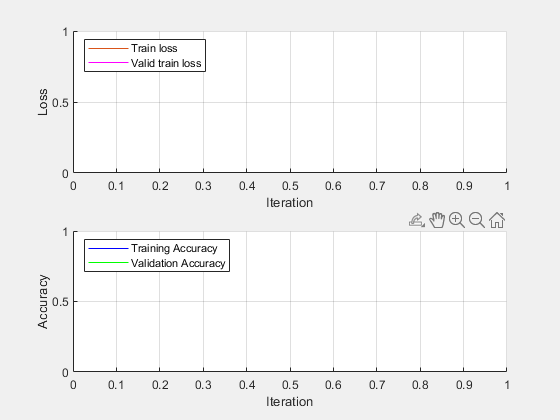

% training loss plot
fig_handle = figure;
set(gcf,'Visible','on');
subplot(2,1,1)
lineLossTrain = animatedline('Color',[0.85 0.325 0.098]);
lineLossValid = animatedline('Color',[1 0 1]);
ylim([0 inf])
xlabel("Iteration")
ylabel("Loss")
legend('Train loss','Valid train loss','Location','northwest');
grid on;

% Accuracy plot
subplot(2,1,2)
trainAccPlotter = animatedline('Color','b');
valAccPlotter = animatedline('Color','g');
legend('Training Accuracy','Validation Accuracy','Location','northwest');
xlabel("Iteration")
ylabel("Accuracy")
grid on;

SGDM用の速度パラメータを初期化

Initialize the velocity parameter for the SGDM solver.

velocity = [];
velocity_out = [];

学習ループ開始

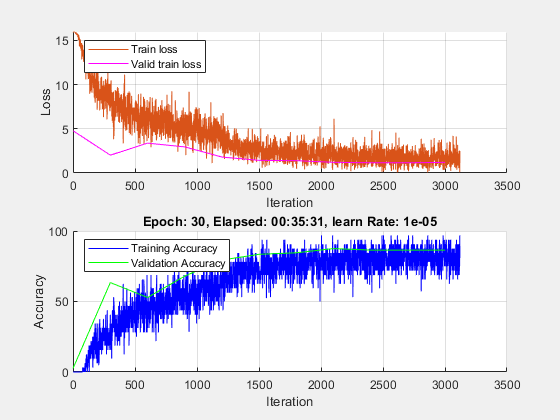

iteration = 0;
start = tic;

dt = datetime('now');
DateString = datestr(dt,'yyyymmddHHMMSS');

% if true, save the trained model and plot in every epoch
save_all_model_flag = false;


ModelDir = "Models_" + DateString + "/";
mkdir(ModelDir);
% tempDir = "Temp_" + DateString + "/";
% mkdir(tempDir);

% Loop over epochs.
for epoch = 1:numEpochs
    % Shuffle data.
    shuffle(mbq);

    learnRate = initialLearnRate * learnDropRate^floor(epoch / dropFrequency);
    
    % Loop over mini-batches.
    while hasdata(mbq)
        iteration = iteration + 1;
        
        % Read mini-batch of data.
        [dlX, dlY] = next(mbq);
        
        % Evaluate the model gradients, state, and loss using dlfeval and the
        % modelGradients function and update the network state.
        [gradients,state,loss,acc] = dlfeval(@modelGradients,dlnet,dlX,dlY);
        dlnet.State = state;
%         loss

        % L2 Regularization
        idx_L2 = dlnet.Learnables.Parameter == "Weights";
        L2Regularizer = @(grad,param) grad + L2Factor.*param;
        %Use dlupdate to apply the regularization function to each of the gradients.
        gradients(idx_L2, :) = dlupdate(L2Regularizer,gradients(idx_L2, :),dlnet.Learnables(idx_L2, :));
        
        
        % Update the network parameters using the SGDM optimizer.
        [dlnet,velocity] = sgdmupdate(dlnet,gradients,velocity,learnRate,momentum);

        %save(tempDir + "dlset_ep" + string(epoch) + "_it" + string(iteration) + ".mat", "dlnet_out", "dlnet", "gradients", "grads_out");
        
        % Display the training progress.
        D = duration(0,0,toc(start),'Format','hh:mm:ss');
        addpoints(lineLossTrain,iteration,loss)
        title("Epoch: " + epoch + ", Elapsed: " + string(D) + ", learn Rate: " + string(learnRate))
        addpoints(trainAccPlotter, iteration, acc * 100.0);
        drawnow

        % validation, this is computed in validation frquency
        if (mod(iteration, val_freq) == 1)
            losses_val = [];
            corrects_val = [];
            samples = 0;
            reset(mbq_val);

            while hasdata(mbq_val)
                 % Read mini-batch of data.
                [dlX_val, Y_val] = next(mbq_val);
                   
                % Make predictions using the predict function.
                dlYPred_val = predict(dlnet, dlX_val, dlarray(zeros(size(Y_val)), "CB"));
                %dlYPred_val = predict(dlnet_out, dlFeat_val, );

                loss_val = crossentropy(dlYPred_val,Y_val);
                %gradients = dlgradient(loss,dlnet.Learnables);

                loss_val = double(gather(extractdata(loss_val)));
                losses_val = [losses_val loss_val];

                [~, true_idx] = max(extractdata(gather(Y_val)));
                [~, pred_idx] = max(extractdata(gather(dlYPred_val)));
                num_correct = nnz(true_idx == pred_idx);
                corrects_val = [corrects_val num_correct];
            end
            
            % Display the training progress of validation
            addpoints(lineLossValid, iteration, mean(losses_val))
            accuracy_val = sum(corrects_val) / augimdsValidation.NumObservations;
            addpoints(valAccPlotter, iteration, accuracy_val * 100.0);
            drawnow
        end
    end
    if save_all_model_flag
        save(ModelDir+"dlnet_epoch" + string(epoch) + ".mat", "dlnet", "classes", "inputSize");
        savefig(fig_handle, ModelDir + "train_ep" + string(epoch) + ".fig");
    end
end

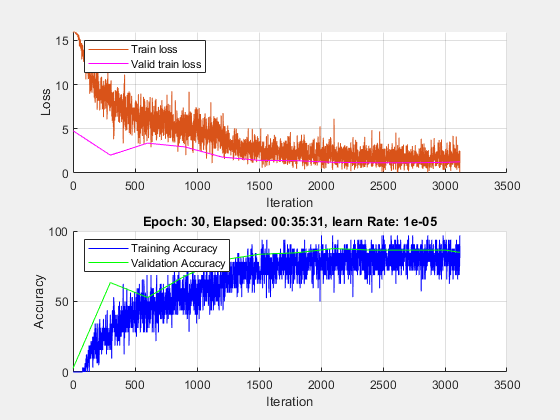

% last validation
losses_val = [];
corrects_val = [];
samples = 0;
reset(mbq_val);

while hasdata(mbq_val)
     % Read mini-batch of data.
    [dlX_val, Y_val] = next(mbq_val);
       
    % Make predictions using the predict function.
    dlYPred_val = predict(dlnet, dlX_val,  dlarray(zeros(size(Y_val)), "CB"));

    loss_val = crossentropy(dlYPred_val,Y_val);

    loss_val = double(gather(extractdata(loss_val)));
    losses_val = [losses_val loss_val];

    [~, true_idx] = max(extractdata(gather(Y_val)));
    [~, pred_idx] = max(extractdata(gather(dlYPred_val)));
    num_correct = nnz(true_idx == pred_idx);
    corrects_val = [corrects_val num_correct];
end

addpoints(lineLossValid, iteration, mean(losses_val))
accuracy_val = sum(corrects_val) / augimdsValidation.NumObservations;
addpoints(valAccPlotter, iteration, accuracy_val * 100.0);

drawnow

% save trained model
save(ModelDir+"dlnet_end.mat", "dlnet", "classes", "inputSize");
savefig(fig_handle, ModelDir + "train_end.fig");

## Test Model

顔だけ切り取った画像を用意

prepare pet face images 

## test images

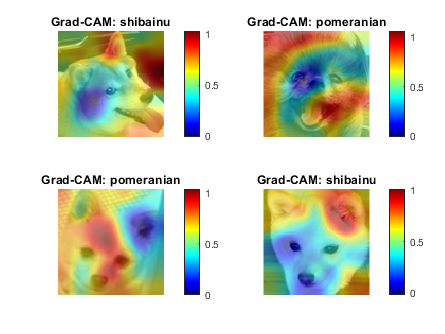

cl = 1×1 cell array
    {'shibainu'}


cl2 = categorical
     shibainu 


cl = 1×1 cell array
    {'pomeranian'}


cl2 = categorical
     pomeranian 


cl = 1×1 cell array
    {'pomeranian'}


cl2 = categorical
     pomeranian 


cl = 1×1 cell array
    {'shibainu'}


cl2 = categorical
     shibainu 


%if training is executed, this loading should comment out. 学習した場合はコメントアウト
load dlnet_end.mat

%% Input your test image files in this folder
image_dir = "./data/test/";
%% Input your image filename in this list
img_files = ["shiba1.jpg",...
    "pome1.png", ...
    "koma1.jpg", "koma2.jpg"];

img_set = zeros([inputSize(1), inputSize(2), 3, numel(img_files)]);
counter = 1;
figure;
f = tiledlayout("flow");
set(f, 'visible', "on");
cls = [];
preds = [];
feats = [];
dists = [];

for fn = img_files
    img = imread(image_dir + fn);
    img_resize = double(imresize(img, inputSize(1:2)));
    img_set(:, :, :, counter) = img_resize;
    [cl, pred, feat, dist] = predictIm(dlnet, img_resize, classes);

    ax = nexttile;
    imshow(img, "Parent", ax);
    title(ax, cl);
    %nexttile

    counter = counter + 1;

    cls = [cls, cl];
    preds = [preds, pred];
    feats = [feats, feat];
    dists = [dists, dist];

    %if you try grad cam
    gradCAM_dl(img_resize, dlnet, 'softmax', 'activation_40_relu', classes);
end


if ~exist("results/", "dir")
    mkdir("results/");
end
counter = 1

counter = 1

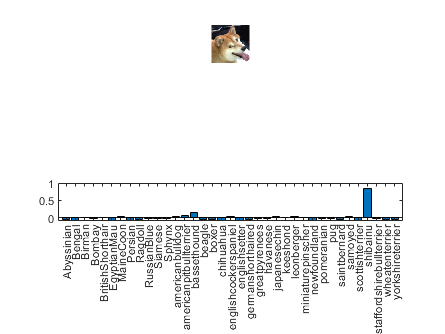

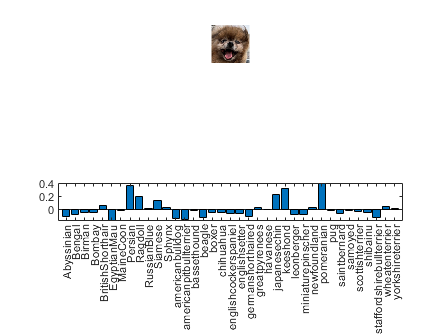

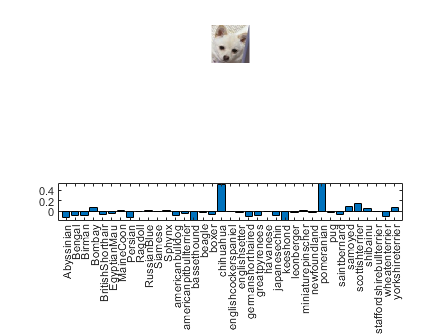

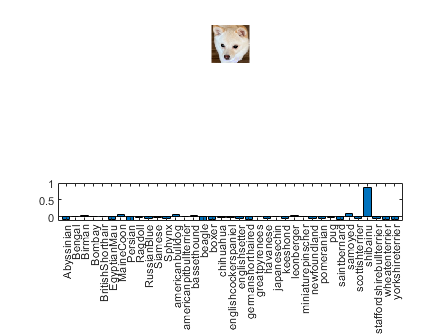

for fn = img_files
    figure
    ax_sp(1) = subplot(2, 1, 1);
    imshow(uint8(img_set(:, :, :, counter)), "Parent", ax_sp(1));
    ax_sp(2) = subplot(2, 1, 2);
    bar(ax_sp(2), categorical(classes), dists(:, counter));
    exportgraphics(gcf, "results/" + fn);
    exportgraphics(gcf, "results/" + fn + ".pdf");

    counter = counter + 1;
end

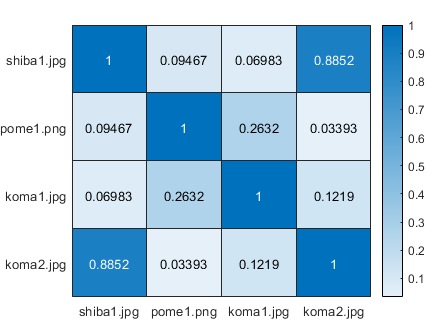


%　それぞれの画像の類似度を計算 512次元の特徴量のcosine類似度
% calculate pet images similarity. 512 dimesion feature cosine similarity
feats = gather(feats);
feats_normed = feats ./ vecnorm(feats, 2, 1);
similarities = feats_normed' * feats_normed;

figure
heatmap(img_files, img_files, similarities);

% 学習した画像を使用して類似度を計算するテスト
% 青色でArcFaceペナルティなしの類似度、オレンジ色でペナルティありの類似度を表示
% test of calculating the similarity by using trained images
% blue bar shows the similarity without arcface margin, orange bar shows
% the similarity with arcface margin

shuffle(mbq);
[dlX, dlY] = next(mbq);

[dlYPred,dists] = predict(dlnet, dlX, dlarray(zeros(size(dlY)), "CB"), 'Outputs', {'softmax', 'ArcFaceLayer'});
[dlYPred_penalty,dists_penalty] = forward(dlnet, dlX, dlarray(dlY, "CB"), 'Outputs', {'softmax', 'ArcFaceLayer'});

dists = gather(extractdata(dists)) ./ dlnet.Layers(177).scale;
dists_penalty = gather(extractdata(dists_penalty)) ./ dlnet.Layers(177).scale;

Y = extractdata(gather(dlY));
[~, true_idx] = max(Y);
[~, pred_idx] = max(extractdata(gather(dlYPred)));

counter = 1;
for idx_img = 1:8
    figure
    ax_sp(1) = subplot(2, 1, 1);
    img = uint8(gather(extractdata(dlX(:, :, :, idx_img))));
    imshow(img, "Parent", ax_sp(1));
    ax_sp(2) = subplot(2, 1, 2);
    bar(ax_sp(2), categorical(classes), [dists(:, idx_img), dists_penalty(:, idx_img)]);
    figure;
    gradCAM_dl(img, dlnet, 'softmax', 'activation_40_relu', classes);

    counter = counter + 1;
end

function gradCAM_dl(img, dlnet, softmaxName, featureLayerName, classes)
    inputSize = dlnet.Layers(1).InputSize(1:2);
    img = imresize(img, inputSize);
%     inputSize = size(img, 1:2);
    num_class = numel(classes);
    batch_num = 1;
    
    % 自動微分を使用するには、イメージを dlarray に変換します。
    dlImg = dlarray(single(img),'SSC');
    
    dlY = predict(dlnet, dlImg, dlarray(zeros(num_class, batch_num), "CB"));
    pred = extractdata(dlY);
    
    [val, idx] = max(pred);
    classfn = classes{idx};
    cl2 = onehotdecode(pred, classes, 1)';
    
    % 関数 gradcam で dlfeval を呼び出すことによって、イメージの Grad-CAM 勾配を計算します。
    [featureMap, dScoresdMap] = dlfeval(@gradcam, dlnet, dlImg, softmaxName, featureLayerName, idx);
    
    %イメージ サイズへの勾配マップのサイズを変更し、スコアを表示に適したレベルにスケーリングします。
    gradcamMap = sum(featureMap .* sum(dScoresdMap, [1 2]), 3);
    gradcamMap = extractdata(gradcamMap);
    gradcamMap = rescale(gradcamMap);
    gradcamMap = imresize(gradcamMap, inputSize, 'Method', 'bicubic');
    
    % 'AlphaData' の値として 0.5 を使用して、イメージの上に Grad-CAM レベルを表示します。'jet' カラーマップでは、濃い青が最低値、濃い赤が最高値になっています。
    imshow(uint8(img));
    hold on;
    imagesc(gradcamMap,'AlphaData',0.5);
    colormap jet
    colorbar
    hold off;
    title("Grad-CAM: " + string(classfn));
end
function [featureMap,dScoresdMap] = gradcam(dlnet, dlImg, softmaxName, featureLayerName, classfn)
    classnum = dlnet.Layers(end).InputSize;
    [scores,featureMap] = predict(dlnet, dlImg, dlarray(zeros(classnum), 'CB'), 'Outputs', {softmaxName, featureLayerName});
    classScore = scores(classfn);
    dScoresdMap = dlgradient(classScore,featureMap);
end

function [cl, pred, feat, dist] = predictIm(dlnet, image, classes)
    
    dlX = dlarray(image, "SSCB");

    batch_num = size(image, 4);
    num_class = numel(classes);
    %dlFeat = predict(dlnet, dlX);
    [dlY, dist, dlFeat] = predict(dlnet, dlX, dlarray(zeros(num_class, batch_num), "CB"), 'Outputs', {'softmax', 'ArcFaceLayer', 'fc_output'});

    feat = extractdata(dlFeat);
    pred = extractdata(dlY);
    dist = extractdata(gather(dist)) ./ dlnet.Layers(177).scale;

    [val, idx] = max(pred);
    cl = classes(idx)
    cl2 = onehotdecode(pred, classes, 1)'
end


## Model Gradients Function

function [gradients,state,loss,acc] = modelGradients(dlnet,dlX,Y)

[dlYPred,state] = forward(dlnet, dlX, dlarray(Y, "CB"));

loss = crossentropy(dlYPred,Y);
gradients = dlgradient(loss,dlnet.Learnables);

loss = double(gather(extractdata(loss)));

Y = extractdata(gather(Y));
[~, true_idx] = max(Y);
[~, pred_idx] = max(extractdata(gather(dlYPred)));
num_correct = nnz(true_idx == pred_idx);
acc = num_correct / size(Y, 2);
end

## Mini Batch Preprocessing Function

function [X,Y] = preprocessMiniBatch(XCell,YCell)

% Preprocess predictors.
X = preprocessMiniBatchPredictors(XCell);

% Extract label data from cell and concatenate.
Y = cat(2,YCell{1:end});

% One-hot encode labels.
Y = onehotencode(Y,1);

end

## Mini-Batch Predictors Preprocessing Function

function X = preprocessMiniBatchPredictors(XCell)

% Concatenate.
X = cat(4,XCell{1:end});

end

function [dataOut,info] = ColorAugmentation(dataIn,info)

    dataOut = cell([size(dataIn,1),2]);
    
    %dataIn
    for idx = 1:size(dataIn,1)
        temp = dataIn.input{idx};
        
        %Saturation augmentation
        temp = jitterColorHSV(temp,'Hue',0.1...
            ,'Saturation',0.3...
            ,'Contrast',0.3);

        % Black white transformation
        BWProbability = 0.1;
        if rand <= BWProbability
            temp = repmat(rgb2gray(temp),[1 1 3]);
        end
        
        % Form second column expected by trainNetwork which is the expected response,
        % the categorical label in this case
        dataOut(idx,:) = {temp,info.Label(idx)};
    end

end

*Copyright 2022 Nobuaki Fukuchi*